# **神经网络反向传播主程序**

%% Initialization
clear ; close all; clc

%% Setup the parameters you will use for this exercise
input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10   
                          % (note that we have mapped "0" to label 10)

times = 50;
step = 1;
times_start = 0;
times_end= times_start + step*times;
acc_times = zeros(1,times+1);
for i = 0:times
fprintf(['------------------------第 %d 轮--------------------------\n'],i);
%% =========== Part 1: 加载和可视化数据 =============
%  We start the exercise by first loading and visualizing the dataset. 
%  You will be working with a dataset that contains handwritten digits.
% Load Training Data
load('ex1data.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
% displayData(X(sel, :));
fprintf('数据已经加载完成并可视化。\n');

%% ================ Part 2: 加载参数 ================
% In this part of the exercise, we load some pre-initialized neural network parameters.
% Load the weights into variables Theta1 and Theta2
load('ex1weights.mat');

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];
fprintf('参数已经加载完成。\n');

%% ================ Part 3: 计算成本（前向） ================
%  To the neural network, you should first start by implementing the feedforward part of the neural network that returns the cost only.
%  You should complete the code in nnCostFunction.m to return cost. 
%  After implementing the feedforward to compute the cost, 
%  you can verify that your implementation is correct by verifying that you get the same cost as us for the fixed debugging parameters.
%
%  We suggest implementing the feedforward cost *without* regularizationfirst so that it will be easier for you to debug.
%  Later, in part 4, you will get to implement the regularized cost.

% Weight regularization parameter (we set this to 0 here).
lambda = 0;
J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, ...
                   num_labels, X, y, lambda);

fprintf(['Cost at parameters (loaded from ex1weights): %f '...
         '\n(this value should be about 0.288401 )\n'], J);
fprintf('\n第三部分完成\n');

%% =============== Part 4: 实现正则化 ===============
%  Once your cost function implementation is correct, 
%  you should now continue to implement the regularization with the cost.

% Weight regularization parameter (we set this to 1 here).
lambda = 1;
J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, ...
                   num_labels, X, y, lambda);

fprintf(['Cost at parameters (loaded from ex1weights): %f '...
         '\n(this value should be about 0.408577)\n'], J);
fprintf('第四部分完成。\n');

%% ================ Part 5: 计算激活函数Sigmoid的梯度 ================
%  Before you start implementing the neural network, 
%  you will first implement the gradient for the sigmoid function. 
%  You should complete the code in the sigmoidGradient.m file.

g = sigmoidGradient([1 -0.5 0 0.5 1]);
fprintf('Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:\n  ');
fprintf('%f ', g);
fprintf('\n\n');

fprintf('第五部分完成。\n');

%% ================ Part 6: 初始化参数 ================
%   In this part of the exercise,
%   you will be starting to implment a two layer neural network that classifies digits.
%   You will start byimplementing a function to initialize the weights of the neural network

%   (randInitializeWeights.m)
initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];
fprintf('第六部分完成。\n');

%% =============== Part 7: 实现反向传播 ===============
%  Once your cost matches up with ours, you should proceed to implement the backpropagation algorithm for the neural network. 
%  You should add to the code you've written in nnCostFunction.m to return the partial derivatives of the parameters.

%  Check gradients by running checkNNGradients
checkNNGradients;
fprintf('第七部分完成，但计算出的梯度偏大。\n');

%% =============== Part 8: 实现正则化 ===============
%  Once your backpropagation implementation is correct,
%   you should now continue to implement the regularization with the cost and gradient.

%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);

% Also output the costFunction debugging values
debug_J  = nnCostFunction(nn_params, input_layer_size, ...
                          hidden_layer_size, num_labels, X, y, lambda);
fprintf(['\n\nCost at (fixed) debugging parameters (w/ lambda = 10): %f ' ...
         '\n(this value should be about 0.648928)\n\n'], debug_J);
fprintf('第八部分完成。\n');

%% =================== Part 9: 训练神经网络 ===================
%  You have now implemented all the code necessary to train a neural network.
%  To train your neural network, we will now use "fmincg", which is a function which works similarly to "fminunc". 
%  Recall that these advanced optimizers are able to train our cost functions efficiently as long as we provide them with the gradient computations.

 %%%%%%%%%%%%%%%%%%%%%%%%%% 参数调节 %%%%%%%%%%%%%%%%%%%%%%%%%%
 %  After you have completed the assignment, change the MaxIter to a larger value to see how more training helps.
 test_num = 50;
 options = optimset('MaxIter', test_num);

 %  You should also try different values of lambda
 lambda = 0+step*i;
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, ...
                                   input_layer_size, ...
                                   hidden_layer_size, ...
                                   num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the neural network parameters)
[nn_params, cost] = fmincg(costFunction, initial_nn_params, options);

% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), ...
                 hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), ...
                 num_labels, (hidden_layer_size + 1));

fprintf('第九部分完成。\n');

%% ================= Part 10: 可视化权重 =================
%  You can now "visualize" what the neural network is learning by displaying the hidden units  
%  to see what features they are capturing in the data.

% displayData(Theta1(:, 2:end));
fprintf('第十部分完成。\n');

%% ================= Part 11: 实现预测 =================
%  After training the neural network, we would like to use it to predict the labels. 
%  You will now implement the "predict" function to use the neural network to predict the labels of the training set.
%  This lets you compute the training set accuracy.
pred = predict(Theta1, Theta2, X);
acc_times(i+1)=mean(double(pred == y)) * 100;
fprintf('\n训练集准确性: %f\n', acc_times(i+1));
fprintf('======================全部完成=====================\n');
end

------------------------第 0 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 96.275000


======================全部完成=====================


------------------------第 1 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 96.250000


======================全部完成=====================


------------------------第 2 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 95.225000


======================全部完成=====================


------------------------第 3 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 95.225000


======================全部完成=====================


------------------------第 4 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 94.600000


======================全部完成=====================


------------------------第 5 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 93.525000


======================全部完成=====================


------------------------第 6 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 93.675000


======================全部完成=====================


------------------------第 7 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 94.025000


======================全部完成=====================


------------------------第 8 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 92.550000


======================全部完成=====================


------------------------第 9 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 92.500000


======================全部完成=====================


------------------------第 10 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 92.825000


======================全部完成=====================


------------------------第 11 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 92.575000


======================全部完成=====================


------------------------第 12 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 92.250000


======================全部完成=====================


------------------------第 13 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 92.375000


======================全部完成=====================


------------------------第 14 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 91.900000


======================全部完成=====================


------------------------第 15 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 92.000000


======================全部完成=====================


------------------------第 16 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 91.500000


======================全部完成=====================


------------------------第 17 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 91.750000


======================全部完成=====================


------------------------第 18 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 91.825000


======================全部完成=====================


------------------------第 19 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 91.375000


======================全部完成=====================


------------------------第 20 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 91.275000


======================全部完成=====================


------------------------第 21 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 91.225000


======================全部完成=====================


------------------------第 22 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 90.825000


======================全部完成=====================


------------------------第 23 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 91.050000


======================全部完成=====================


------------------------第 24 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 90.900000


======================全部完成=====================


------------------------第 25 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 90.325000


======================全部完成=====================


------------------------第 26 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 90.575000


======================全部完成=====================


------------------------第 27 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 90.600000


======================全部完成=====================


------------------------第 28 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 90.525000


======================全部完成=====================


------------------------第 29 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 90.300000


======================全部完成=====================


------------------------第 30 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 90.275000


======================全部完成=====================


------------------------第 31 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 89.600000


======================全部完成=====================


------------------------第 32 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 89.775000


======================全部完成=====================


------------------------第 33 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 89.775000


======================全部完成=====================


------------------------第 34 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 89.850000


======================全部完成=====================


------------------------第 35 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 89.900000


======================全部完成=====================


------------------------第 36 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 89.850000


======================全部完成=====================


------------------------第 37 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 88.700000


======================全部完成=====================


------------------------第 38 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 89.125000


======================全部完成=====================


------------------------第 39 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 88.925000


======================全部完成=====================


------------------------第 40 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 89.200000


======================全部完成=====================


------------------------第 41 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 89.100000


======================全部完成=====================


------------------------第 42 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 88.000000


======================全部完成=====================


------------------------第 43 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 88.975000


======================全部完成=====================


------------------------第 44 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 88.475000


======================全部完成=====================


------------------------第 45 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 88.900000


======================全部完成=====================


------------------------第 46 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 88.125000


======================全部完成=====================


------------------------第 47 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 88.525000


======================全部完成=====================


------------------------第 48 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 88.150000


======================全部完成=====================


------------------------第 49 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 88.550000


======================全部完成=====================


------------------------第 50 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


第九部分完成。


第十部分完成。



训练集准确性: 87.900000


======================全部完成=====================


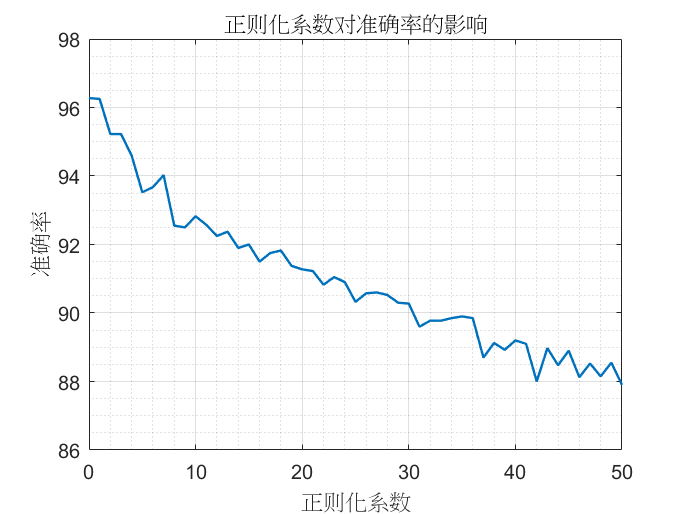



figure();
f1=plot(times_start:step:times_end,acc_times);
set(f1, 'LineWidth', 1.2); % 使用句柄修改线条粗细
title("正则化系数对准确率的影响")
xlabel('正则化系数')
ylabel('准确率')
grid on;grid minor;